## Prep work

% load the data in + test/train
data = readtable("ChinaTotal.csv")

data = 117×2 table
    Year    Total 
    ____    ______

    1907    19.894
    1908    22.736
    1909    24.252
    1910    25.009
    1911    24.631
    1912    17.029
    1913    24.252
    1914    26.718
    1915    25.421
    1916    30.131
    1917    32.023
    1918    34.748
    1919    37.997
    1920    40.278
    1921    38.763
    1922    39.972


splitYear = 2018;

trainData = data(data.Year <= splitYear, :);
testData = data(data.Year > splitYear, :);

## Addressing Heteroscedasticity

trainData.logTotal = log(trainData.Total)

trainData = 112×3 table
    Year    Total     logTotal
    ____    ______    ________

    1907    19.894     2.9904 
    1908    22.736     3.1239 
    1909    24.252     3.1885 
    1910    25.009     3.2193 
    1911    24.631      3.204 
    1912    17.029     2.8349 
    1913    24.252     3.1885 
    1914    26.718     3.2854 
    1915    25.421     3.2356 
    1916    30.131     3.4055 
    1917    32.023     3.4665 
    1918    34.748     3.5481 
    1919    37.997     3.6375 
    1920    40.278     3.6958 
    1921    38.763     3.6575 
    1922    39.972     3.6882 


trainData.logTotal = log(trainData.Total+1)

trainData = 112×3 table
    Year    Total     logTotal
    ____    ______    ________

    1907    19.894     3.0395 
    1908    22.736      3.167 
    1909    24.252     3.2289 
    1910    25.009     3.2585 
    1911    24.631     3.2438 
    1912    17.029      2.892 
    1913    24.252     3.2289 
    1914    26.718     3.3221 
    1915    25.421     3.2741 
    1916    30.131     3.4382 
    1917    32.023     3.4972 
    1918    34.748     3.5765 
    1919    37.997     3.6635 
    1920    40.278     3.7203 
    1921    38.763     3.6829 
    1922    39.972     3.7129 



originalRange = [min(trainData.Total), max(trainData.Total)]

originalRange = 1.0e+04 *

    0.0017    1.0333


transformedRange = [min(trainData.logTotal), max(trainData.logTotal)]

transformedRange =     2.8920    9.2432


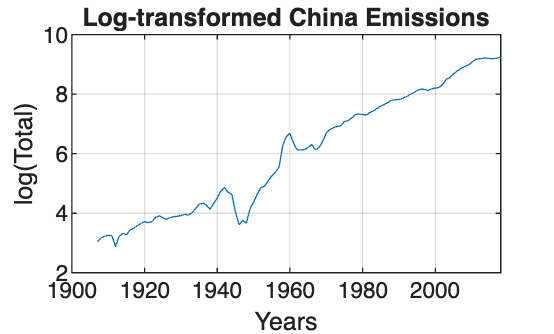


% visuals
figure;
plot(trainData.Year, trainData.logTotal);
xlabel("Years");
ylabel("log(Total)");
title("Log-transformed China Emissions");
grid on;

## Comparing OG to Log

statsTotal = table();
statsTotal.mean_Total = mean(data.Total);
statsTotal.std_Total = std(data.Total);

figure
tiledlayout(1,2)
nexttile
scatter(statsTotal.mean_Total, statsTotal.std_Total, 'DisplayName', 'std_Total');
xlabel("mean\_Total")
ylabel("std\_Total")
title("Mean vs. Standard Deviation","Original Data")
grid on
lsline

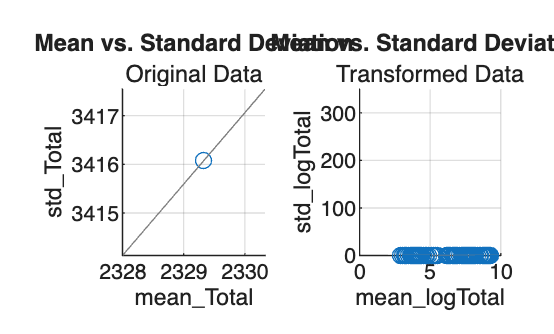


statsLogGHI = groupsummary(trainData,"Year",["mean","std"],"logTotal");
nexttile
scatter(statsLogGHI.mean_logTotal, statsLogGHI.std_logTotal, 'DisplayName', 'std_logTotal');
xlabel("mean\_logTotal")
ylabel("std\_logTotal")
title("Mean vs. Standard Deviation","Transformed Data")
grid on
ylim([0 350])
lsline

## Decomposing Data

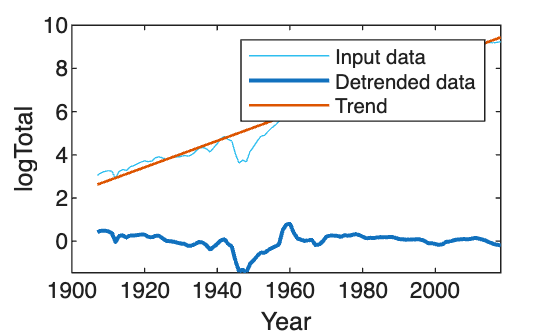

% Remove trend from input data
newTable3 = detrend(trainData(:,"logTotal"),SamplePoints=trainData.Year);

% Extract trend from input data
linTrends = trainData(:,"logTotal");
linTrends.(1) = linTrends.(1) - newTable3.(1);

% Display results
figure
plot(trainData.Year,trainData.logTotal,SeriesIndex=6, ...
    DisplayName="Input data")
hold on
plot(trainData.Year,newTable3.logTotal,SeriesIndex=1,LineWidth=1.5, ...
    DisplayName="Detrended data")
plot(trainData.Year,linTrends.logTotal,SeriesIndex=2,LineWidth=1, ...
    DisplayName="Trend")
hold off
legend
ylabel("logTotal")
xlabel("Year")

clear newTable3

trainData.linDetrended = trainData.logTotal - linTrends.logTotal

trainData = 112×4 table
    Year    Total     logTotal    linDetrended
    ____    ______    ________    ____________

    1907    19.894     3.0395        0.41915  
    1908    22.736      3.167        0.48523  
    1909    24.252     3.2289        0.48567  
    1910    25.009     3.2585        0.45379  
    1911    24.631     3.2438        0.37766  
    1912    17.029      2.892      -0.035585  
    1913    24.252     3.2289        0.23986  
    1914    26.718     3.3221        0.27161  
    1915    25.421     3.2741        0.16221  
    1916    30.131     3.4382         0.2648  
    1917    32.023     3.4972        0.26237  
    1918    34.748     3.5765        0.28019  
    1919    37.997     3.6635        0.30574  
    1920    40.278     3.7203        0.30113  
    1921    38.763     3.6829        0.20227  
    1922    39.972     3.7129        0.1


% idk if this is seasonal...might be long term depending on criteria

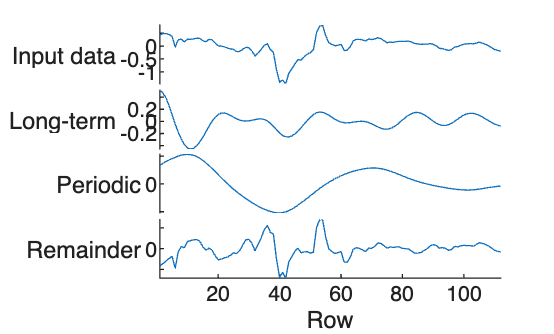

% Decompose data into long-term trend, seasonal trends, and remainder
trends = trenddecomp(trainData(:,"linDetrended"),"ssa",47,NumSeasonal=1);

% Display results
figure
stackedplot([trainData(:,4) trends],"DisplayLabels",["Input data","Long-term", ...
    "Periodic","Remainder"]);

% all together now
trends

trends = 112×3 table
    linDetrended_LongTerm    linDetrended_Seasonal    linDetrended_Remainder
    _____________________    _____________________    ______________________

             0.511                  0.33599                  -0.42783       
           0.47408                  0.37035                   -0.3592       
            0.3872                  0.40121                  -0.30274       
           0.26135                  0.42915                  -0.23671       
           0.11246                    0.454                   -0.1888       
          -0.04182                  0.47629                  -0.47006       
          -0.17846                  0.49906                 -0.080737       
          -0.29528                   0.5167                   0.05019       
          -0.38415                  0.52754                  0.018813       
          -0.43797           

linTrends

linTrends = 112×1 table
    logTotal
    ________

     2.6203 
     2.6818 
     2.7432 
     2.8047 
     2.8661 
     2.9276 
      2.989 
     3.0505 
     3.1119 
     3.1734 
     3.2348 
     3.2963 
     3.3578 
     3.4192 
     3.4807 
     3.5421 


allComponents = table;
allComponents.LinComp = linTrends.logTotal;
allComponents.LongTermComp = trends.linDetrended_LongTerm;
allComponents.SeasComp = trends.linDetrended_Seasonal;

remainingTS = table;
remainingTS.Remainder = round(trends.linDetrended_Remainder,4)

remainingTS = 112×1 table
    Remainder
    _________

     -0.4278 
     -0.3592 
     -0.3027 
     -0.2367 
     -0.1888 
     -0.4701 
     -0.0807 
      0.0502 
      0.0188 
      0.1714 
      0.1931 
      0.2115 
      0.2187 
      0.1822 
      0.0428 
     -0.0338 


### Linear Model

% allComponents
%function [fitresult, gof] = createFit(LinComp)
%CREATEFIT(LINCOMP)
%  Create a fit.
%
%  Data for 'untitled fit 1' fit:
%      Y Output: LinComp from allComponents
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 17-Oct-2025 09:57:24


%% Fit: 'untitled fit 1'.
%[xData, yData] = prepareCurveData( [], LinComp );

% Set up fittype and options.
%ft = fittype( 'poly1' );

% Fit model to data.
%[fitresult, gof] = fit( xData, yData, ft );

% Plot fit with data.
%figure( 'Name', 'untitled fit 1' );
%h = plot( fitresult, xData, yData );
%legend( h, 'LinComp', 'untitled fit 1', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
%ylabel( 'LinComp', 'Interpreter', 'none' );
%grid on

%LinMdl = createLinFit(allComponents.LinComp)
%title("Linear Model")
%end

### Long Term Model

%function [fitresult, gof] = createFit(LongTermComp)
%CREATEFIT(LONGTERMCOMP)
%  Create a fit.
%
%  Data for 'untitled fit 1' fit:
%      Y Output: LongTermComp from allComponents
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 17-Oct-2025 10:33:33


%% Fit: 'untitled fit 1'.
%[xData, yData] = prepareCurveData( [], LongTermComp );

% Set up fittype and options.
%ft = fittype( 'sin5' );
%opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
%opts.Display = 'Off';
%opts.Lower = [-Inf 0 -Inf -Inf 0 -Inf -Inf 0 -Inf -Inf 0 -Inf -Inf 0 -Inf];
%opts.Robust = 'Bisquare';
%opts.StartPoint = [0.179873929371251 0.202683397005793 2.48255265165725 0.136649408975915 0.405366794011586 -0.295007039221903 0.0586633055772773 0.135122264670529 2.36642545722039 0.0454408727680992 0.472927926346851 -0.312571753746354 0.0457959722843048 0.0337805661676322 -3.03190812465492];

% Fit model to data.
%[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
%figure( 'Name', 'untitled fit 1' );
%h = plot( fitresult, xData, yData );
%legend( h, 'LongTermComp', 'untitled fit 1', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
%ylabel( 'LongTermComp', 'Interpreter', 'none' );
%grid on
%LongTermMdl = createLTFit(allComponents.LongTermComp)
%title("Long-Term Model")
%end

### Seasonal Model

%function [fitresult, gof] = createFit(SeasComp)
%CREATEFIT(SEASCOMP)
%  Create a fit.
%
%  Data for 'untitled fit 1' fit:
%      Y Output: SeasComp from allComponents
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 17-Oct-2025 11:04:53


%% Fit: 'untitled fit 1'.
%[xData, yData] = prepareCurveData( [], SeasComp );

% Set up fittype and options.
%ft = fittype( 'sin6' );
%opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
%opts.Display = 'Off';
%opts.Lower = [-Inf 0 -Inf -Inf 0 -Inf -Inf 0 -Inf -Inf 0 -Inf -Inf 0 -Inf -Inf 0 -Inf];
%opts.StartPoint = [0.247109654926556 0.135122264670529 -0.656808775474961 0.41837334332538 0.0675611323352644 2.23227150519435 0.195474070043695 0.0337805661676322 1.07610540276011 0.0582519568461161 0.202683397005793 -0.839825990327326 0.0311726689210232 0.270244529341057 -0.786307442095032 0.0164971203837421 0.337805661676322 -3.03905901238276];

% Fit model to data.
%[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
%figure( 'Name', 'untitled fit 1' );
%h = plot( fitresult, xData, yData );
%legend( h, 'SeasComp', 'untitled fit 1', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
%ylabel( 'SeasComp', 'Interpreter', 'none' );
%grid on
%SeasMdl = createSeasFit(allComponents.SeasComp)
%title("Seasonal Model")

## Forecasting

y = remainingTS.Remainder

y =    -0.4278
   -0.3592
   -0.3027
   -0.2367
   -0.1888
   -0.4701
   -0.0807
    0.0502
    0.0188
    0.1714
    0.1931
    0.2115
    0.2187
    0.1822
    0.0428


Mdl = arima(1, 1, 1);
EstMdl = estimate(Mdl, y);

 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0024821       0.015731       0.15778         0.87463
    AR{1}         0.16244        0.31375       0.51774         0.60464
    MA{1}         0.12277        0.31229       0.39313         0.69422
    Variance      0.01792      0.0011882        15.081      2.1729e-51



numForecastSteps = 5;
[yF, yMSE] = forecast(EstMdl, numForecastSteps, 'Y0', y);

rmse = sqrt(mean((testData - yF).^2));
fprintf('RMSE = %.4f\n', rmse{:,:});

RMSE = 2021.0805
RMSE = 11272.0149


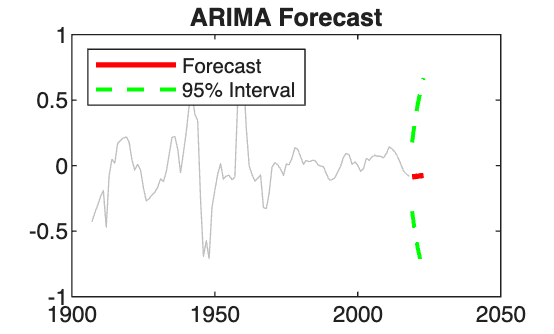


upper = yF + 1.96*sqrt(yMSE);
lower = yF - 1.96*sqrt(yMSE);

startYear = 1907;   % starting year
trainYears = (startYear : startYear + length(y) - 1)'; 
futureYears = (trainYears(end) + 1 : trainYears(end) + numForecastSteps)';

% Plot the results
figure
plot(trainYears, y, 'Color', [.75,.75,.75]) % Plot original data
hold on
h1 = plot(futureYears, yF, 'r', 'LineWidth', 2); % Plot forecasts
h2 = plot(futureYears, upper, 'g--', 'LineWidth', 1.5); % Plot upper confidence bound
plot(futureYears, lower, 'g--', 'LineWidth', 1.5); % Plot lower confidence bound
legend([h1 h2], 'Forecast', '95% Interval', 'Location', 'NorthWest')
title('ARIMA Forecast')
hold off